clear
hold on 
x=[1,2];
Network=init_network();
y=forwoad(x,Network);
t=[0.1,0.9];
e=cross_entropy_error(y,t);
i=0;
i,e,y

i = 0

e = 0.0182

y =     0.3240    0.7123


lmt=0.008

lmt = 0.0080

while e>0.01
    i=i+1;
    Network=backword(Network,x,lmt);
    y=forwoad(x,Network);
    e=cross_entropy_error(y,t);
    i,e,y
    plot(i,e,'o');
    lmt=lmt-0.005;
end

i = 1

e = 0.0097

y =     0.3166    0.7029


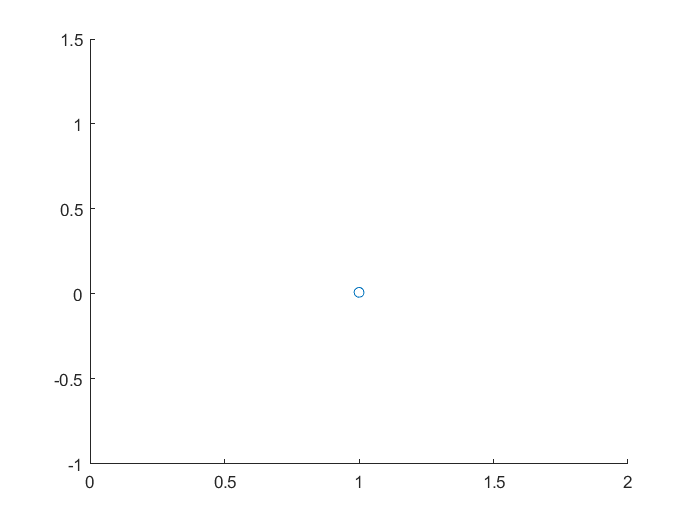

hold off

function network=init_network()
    W1=[0.1, 0.3, 0.5;0.2, 0.4, 0.6];
    b1=[0.1, 0.2, 0.3];
    W2=[0.1, 0.4;0.2, 0.5;0.3, 0.6];
    b2=[0.1, 0.2];
    W3=[0.1, 0.3;0.2, 0.4];
    b3=[0.1, 0.2];
    network={W1,b1,W2,b2,W3,b3};
end

function y=forwoad(x,Network)
    W1=Network{1};
    b1=Network{2};
    W2=Network{3};
    b2=Network{4};
    W3=Network{5};
    b3=Network{6};

    a1 = x* W1 + b1;
    z1 = sigmoid(a1);
    a2 = z1* W2 + b2;
    z2 = sigmoid(a2);
    a3 = z2* W3 + b3;
    y=identity_function(a3);
end

function Network=backword(network,x,e)
    W1=network{1};
    b1=network{2};
    W2=network{3};
    b2=network{4};
    W3=network{5};
    b3=network{6};
   
    a1 = x* W1 + b1;
    z1 = sigmoid(a1);
    a2 = z1* W2 + b2;
    z2 = sigmoid(a2);
    
    network{5}=W3-e.*(ones(2,1)*z2);
    network{3}=W2-e.*(W3*back_sigmoid(z2')*z1)';
  
    
    Network=network;
end
    

function z=sigmoid(x)
    z=1 ./ (1 + exp(-x));
end

function x=identity_function(x)
    x=x;
end

function dy = back_sigmoid(y)
    dy= y.*(1-y);
end

function e=cross_entropy_error(y,t)
    batch_size = length(y);
    e=sum(y-t) / batch_size;
end

